# **Rame de métro**

%warning('off','all')
close all
clear variables

% saisie du nombre de point
nb_point = 100;

% récupérations des données du problèmes rassemblés dans une fonction en
% bas du script
donne = recupe_data(nb_point);
t0 = donne(1);
tf = donne(2);
h = donne(3);
L = donne(4);
vmax = donne(5);
gamma_min = donne(6);
gamma_max = donne(7);
D_securite = donne(8);
delta_gamma_max = donne(9);

[t_tab,x_train1] = train1(t0,tf,h,L);

t_depart = find(x_train1 > D_securite,1); % date à laquelle la rame est autorisé à partir
gammas_ini = ones(1,nb_point);

% Fonction objectif à minimiser (energie)
g = @(X) max(X.*integre(t_tab,X),0);           % calcul de gama(t)*v(t)
Energie = @(X) trapz(t_tab,g(X));        % intégral de gama(t)*v(t)

% Contraintes linéraire
Aeq = zeros(t_depart+1,nb_point);
for i=1:1:t_depart
    Aeq(i,i)=1;
end
Aeq(t_depart+1,nb_point)=1;
beq = zeros(1,t_depart+1);
beq(1,t_depart)=0.1;

% Intervale pour les gammas
lb = gamma_min*gammas_ini;
ub = gamma_max*gammas_ini;

% solveur
options = optimoptions('fmincon', 'Algorithm','sqp', 'MaxIterations', 1000,'ConstraintTolerance', 1e-2, 'OptimalityTolerance', 1e-6, 'StepTolerance', 1e-12, 'MaxFunctionEvaluations', 100000);

[gamma_opt,f,flag,out] = fmincon(Energie,gammas_ini,[],[],Aeq,beq,lb,ub,@Ceq,options)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


gamma_opt =     0.0000    0.0000    0.0007   -0.0005    0.0000   -0.0002   -0.0000   -0.0002   -0.0002   -0.0008    0.0013   -0.0009   -0.0000    0.0000   -0.0046    0.0024    0.0255    0.3050    0.5456    0.7497    0.9493    1.1000    1.1000    1.1000    1.1000    1.0981    1.0949    1.0917    1.0885    1.0853    1.0821    1.0789    1.0757    1.0725    1.0693    1.0661    1.0626    1.0369    0.9892    0.8712    0.6855    0.4783    0.2700    0.1993    0.1328   -0.0425    0.0727    0.2270    0.0643    0.0590


f = 295.7593

flag = 2

out = struct with fields:
         iterations: 15
          funcCount: 1664
          algorithm: 'sqp'
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance and constraints are ↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-12, and the relative maximum constraint↵violation, 7.398882e-05, is less than options.ConstraintTolerance = 1.000000e-02.'
    constrviolation: 0.2078
           stepsize: 2.0198e-12
       lssteplength: 4.0536e-13
      firstorderopt: 18.1555
       bestfeasible: []


## Affichage des résultats

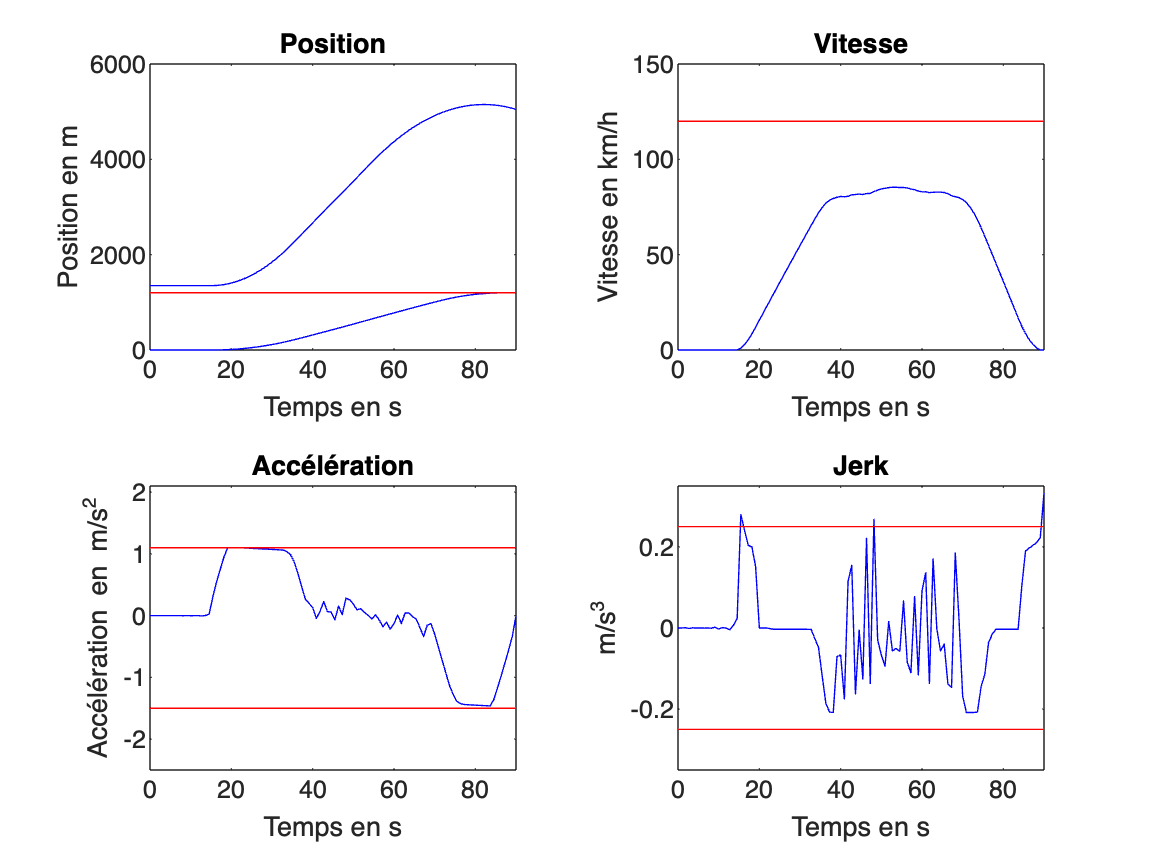

%fonction pour la récupération de la vitesse et de la position du train
vitesse = @(x) integre(t_tab,x);
position = @(x) integre(t_tab,vitesse(x));
v = 3.6*vitesse(gamma_opt);
p = position(gamma_opt);

tiledlayout(2,2);

% Position
nexttile
plot(t_tab,p,'blue',t_tab,1200*gammas_ini,'red',t_tab,x_train1,'blue')
title("Position")
xlim([0 90])
xlabel("Temps en s")
ylabel("Position en m")

% Vitesse
nexttile
plot(t_tab,v,'blue',t_tab,gammas_ini*vmax*3.6,'red')
title("Vitesse")
xlim([0 90])
xlabel("Temps en s")
ylabel("Vitesse en km/h")

% Accélération
nexttile
plot(t_tab,gamma_opt,'blue', t_tab,gammas_ini*gamma_max,'red',t_tab,gammas_ini*gamma_min,'red')
title("Accélération")
xlim([0 90])
ylim([gamma_min-1 gamma_max+1])
ylabel("Accélération en m/s^2")
xlabel("Temps en s")

% Diff accélération
nexttile
plot(t_tab,[0 diff(gamma_opt)],'blue',t_tab,-gammas_ini*delta_gamma_max,'red',t_tab,gammas_ini*delta_gamma_max,'red')
title("Jerk")
xlim([0 90])
ylim([-delta_gamma_max-0.1 delta_gamma_max+0.1])
ylabel("m/s^3")
xlabel("Temps en s")

## Fonction contrainte non linéaires

function [c,ceq] = Ceq(x)
    nb_point = 100;
    % recupération des données du problèmes
    donne = recupe_data(nb_point);
    t0 = donne(1);
    tf = donne(2);
    h = donne(3);
    L = donne(4);
    vmax = donne(5);
    D_securite = donne(8);
    delta_gamma_max = donne(9);

    % récupération de la trajectoire du train 1
    [t_tab,x_train1] = train1(t0,tf,h,L);

    % date de départ
    t_depart = find(x_train1 > D_securite,1);

    % fonctions pour obtenir la position et la vitesse
    vitesse = @(x) integre(t_tab,x);
    position = @(x) integre(t_tab,vitesse(x));

    % formulation des contraintes d'égalité
    xtrain = position(x);                   
    for i=1:1:t_depart
        ceq(i)=xtrain(i);
    end
    ceq(t_depart+1) = xtrain(tf/h)-1200;     % position finale x(t=tf) = 1200
    
    vtrain = vitesse(x); 
    ceq(t_depart+2) = vtrain(tf/h);          % vitesse finale x(t=tf) = 1200
    ceq(t_depart+3) = vtrain(t_depart);      % vitesse initiale v(t=0) = 0
   
    % formulation des contraintes d'inégalité
    c(1,:) = vitesse(x)-vmax;                   % vitesse max à ne pas dépasser
    c(2,:) = -vitesse(x);                       % la vitesse doit être supérieur à zéro
    c(3,:) = abs([diff(x)/h 0])-delta_gamma_max;        % variation de l'accélération à ne pas dépasser
    c(4,:) = D_securite + position(x)-x_train1;

end


## Fonction pour intégrer à partir de deux vecteurs

% fonction pour intégrer deux vecteurs
function inte = integre(t,f)
    l = length(t);
    inte=zeros(1,l);
    for i=2:1:l
        inte(i)=inte(i-1)+(t(i)-t(i-1))*f(i);
    end
end

## Position du train précédent

function [t_lab,x_train1] = train1(to,tf,h,L)
%
% Cette fonction intègre le système d'équations différentielles ordinaires entre t0 et tf
% avec une sauvegarde des résultats sur des pas de temps égaux à h:
%
% dx/dt = v 
% dv/dt = gamma
%
% avec pour conditions initiales : x(t=0) = L ; v(t=0) = 0 
    sol = ode45(@train_1,[to,tf],[0 0]);
    t_lab = to:h:tf;
    y_tab = deval(sol,t_lab);
    x_train1 = y_tab(1,:)+L;
end

function dydt = train_1(t,y)
dydt(1,:)=y(2);
dydt(2,:)= 2.2*tanh(3*t-45)-2.2*tanh(3*t-105)-1.6*tanh(3*t-165)-1.6;
end

## Données

function donnees = recupe_data(nb_point)
    t0 = 0;
    tf = 90;
    h = (tf-t0)/(nb_point-1);
    L = 1350;
    vmax = 120/3.6; % en m/s
    gamma_min = -1.5;
    gamma_max = 1.1;
    D_securite = 1350;
    delta_gamma_max = 0.25;

    donnees = [t0, tf, h, L, vmax, gamma_min, gamma_max, D_securite, delta_gamma_max];
end